imds = imageDatastore('Dataset/Dataset/','IncludeSubfolders',true,'LabelSource','foldernames');

tbl = countEachLabel(imds)

tbl = 5×2 table
        Label         Count
    ______________    _____

    Leveler            12  
    Measuring Tape     13  
    Monitor            17  
    Saw                16  
    Wire Crimper       16  


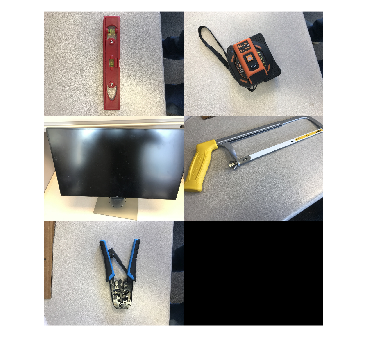

figure
montage(imds.Files(1:16:end))

[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');

bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Leveler
* Image category 2: Measuring Tape
* Image category 3: Monitor
* Image category 4: Saw
* Image category 5: Wire Crimper
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 45 images...done. Extracted 6908700 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 3 has the least number of strongest features: 345600.
** Using the strongest 345600 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1728000
* Number of clusters  

img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


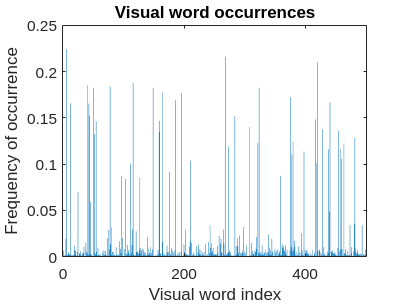


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: Leveler
* Category 2: Measuring Tape
* Category 3: Monitor
* Category 4: Saw
* Category 5: Wire Crimper

* Encoding features for 45 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: Leveler
* Category 2: Measuring Tape
* Category 3: Monitor
* Category 4: Saw
* Category 5: Wire Crimper

* Evaluating 45 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                            PREDICTED
KNOWN             | Leveler   Measuring Tape   Monitor   Saw    Wire Crimper   
-------------------------------------------------------------------------------
Leveler           | 1.00      0.00             0.00      0.00   0.00           
Measuring Tape    | 0.38      0.62             0.00      0.00   0.00           
Monitor           | 0.00      0.00             1.00      0.00   0.00           
Saw               | 0.00      0.00             0.00      1.00   0.00           
Wire Crimper      | 0.00      0.00             0.00      0.00   1.00           

* Average Accuracy is 0.93.



confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: Leveler
* Category 2: Measuring Tape
* Category 3: Monitor
* Category 4: Saw
* Category 5: Wire Crimper

* Evaluating 29 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                            PREDICTED
KNOWN             | Leveler   Measuring Tape   Monitor   Saw    Wire Crimper   
-------------------------------------------------------------------------------
Leveler           | 1.00      0.00             0.00      0.00   0.00           
Measuring Tape    | 0.20      0.80             0.00      0.00   0.00           
Monitor           | 0.00      0.00             1.00      0.00   0.00           
Saw               | 0.00      0.00             0.00      0.67   0.33           
Wire Crimper      | 0.00      0.00             0.00      0.00   1.00           

* Average Accuracy is 0.89.



% Compute average accuracy
mean(diag(confMatrix))

ans = 0.8933

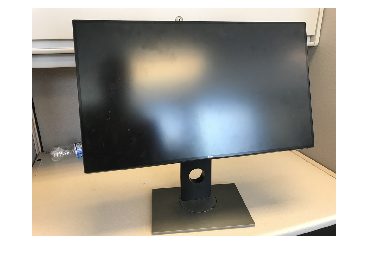

img = imread(fullfile('Dataset/Dataset/Monitor','IMG_7085.JPG'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Monitor'}


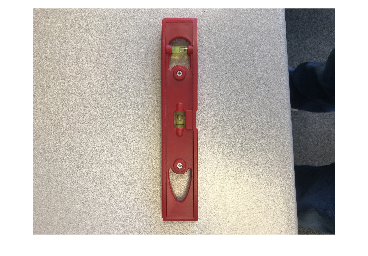

img = imread(fullfile('Dataset/Dataset/Leveler','IMG_7147_70.jpg'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Leveler'}


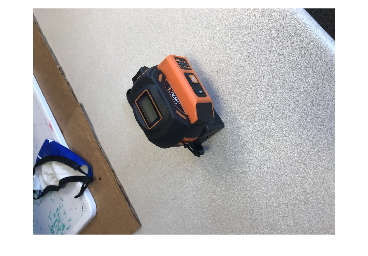

img = imread(fullfile('Dataset/Dataset/Measuring Tape','IMG_7141_70.jpg'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Measuring Tape'}


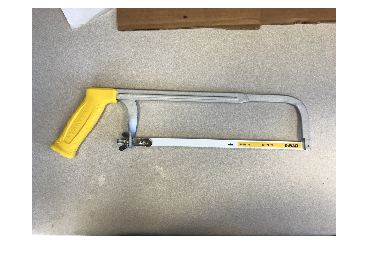

img = imread(fullfile('Dataset/Dataset/Saw','IMG_7102.JPG'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Saw'}


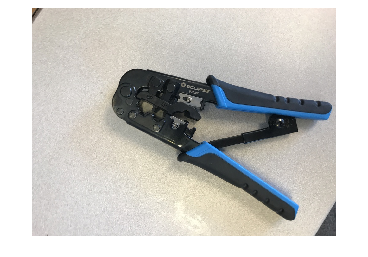

img = imread(fullfile('Dataset/Dataset/Wire Crimper','IMG_7119.JPG'));
figure
imshow(img)

[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.



% Display the string label
categoryClassifier.Labels(labelIdx)

ans = 1×1 cell array
    {'Wire Crimper'}
